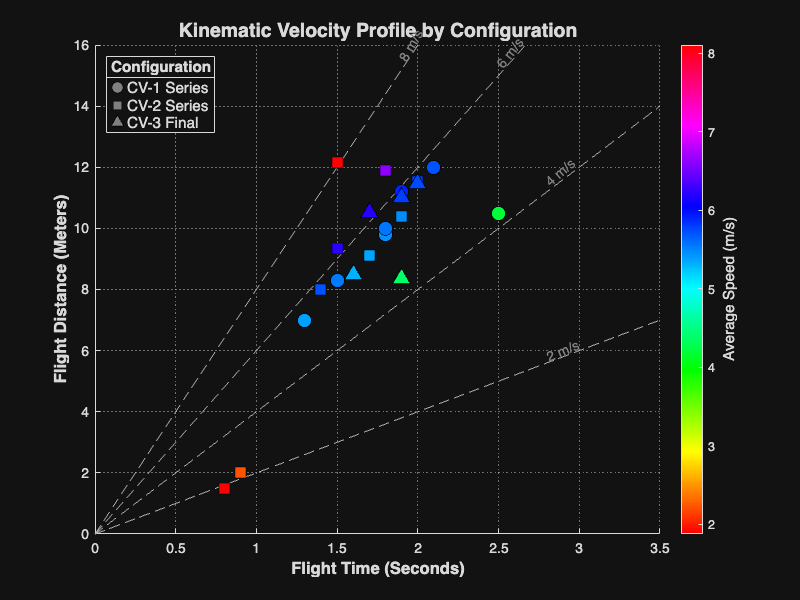



% var setup
distance = [12.0, 10.5, 11.2, 9.8, 7.0, 8.3, 10.0, 9.33, 1.5, 8.0, ...
            2.0, 10.4, 9.11, 11.55, 11.9, 12.16, 8.5, 11.0, 11.48, 8.36, 10.52];
time = [2.1, 2.5, 1.9, 1.8, 1.3, 1.5, 1.8, 1.5, 0.8, 1.4, ...
        0.9, 1.9, 1.7, 2.0, 1.8, 1.5, 1.6, 1.9, 2.0, 1.9, 1.7];

% meth time
speeds = distance ./ time;

% more var defs
cv1_idx = 1:7;     % Tests 11-17 (Dots)
cv2_idx = 8:16;    % Tests 18-26 (Squares)
cv3_idx = 17:21;   % Tests 27-31 (Triangles)

% plotlabing
figure('Position', [100, 100, 800, 600]);
hold on;

t_ref = linspace(0, 3.5, 100);
plot(t_ref, 2 * t_ref, '--', 'Color', [0.7 0.7 0.7]); text(2.8, 5.8, '2 m/s', 'Color', [0.5 0.5 0.5], 'Rotation', 23);
plot(t_ref, 4 * t_ref, '--', 'Color', [0.7 0.7 0.7]); text(2.8, 11.5, '4 m/s', 'Color', [0.5 0.5 0.5], 'Rotation', 41);
plot(t_ref, 6 * t_ref, '--', 'Color', [0.7 0.7 0.7]); text(2.5, 15.3, '6 m/s', 'Color', [0.5 0.5 0.5], 'Rotation', 52);
plot(t_ref, 8 * t_ref, '--', 'Color', [0.7 0.7 0.7]); text(1.9, 15.5, '8 m/s', 'Color', [0.5 0.5 0.5], 'Rotation', 60);


scatter(time(cv1_idx), distance(cv1_idx), 100, speeds(cv1_idx), 'o', 'filled', 'MarkerEdgeColor', 'k');
scatter(time(cv2_idx), distance(cv2_idx), 100, speeds(cv2_idx), 's', 'filled', 'MarkerEdgeColor', 'k');
scatter(time(cv3_idx), distance(cv3_idx), 120, speeds(cv3_idx), '^', 'filled', 'MarkerEdgeColor', 'k');

clim([min(speeds) max(speeds)]); 

% bar of color
cb = colorbar;
cb.Label.String = 'Average Speed (m/s)';
cb.Label.FontSize = 11;
colormap('jet'); %what colors are what change here

% Formatlabing
title('Kinematic Velocity Profile by Configuration', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Flight Time (Seconds)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Flight Distance (Meters)', 'FontSize', 12, 'FontWeight', 'bold');
xlim([0 3.5]);
ylim([0 16]);
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8], 'GridAlpha', 0.5, 'GridLineStyle', ':');
h1 = plot(nan, nan, 'ko', 'MarkerFaceColor', [0.5 0.5 0.5], 'MarkerSize', 8);
h2 = plot(nan, nan, 'ks', 'MarkerFaceColor', [0.5 0.5 0.5], 'MarkerSize', 8);
h3 = plot(nan, nan, 'k^', 'MarkerFaceColor', [0.5 0.5 0.5], 'MarkerSize', 8);
lgd = legend([h1, h2, h3], {'CV-1 Series', 'CV-2 Series', 'CV-3 Final'}, ...
    'Location', 'northwest', 'FontSize', 11);
title(lgd, 'Configuration');
lgd.Box = 'on';

hold off;